# KCF

## Setup

clear;
clc;
format short;

% Parameters
del_t = 1;                                              % time step
itr = 100;                                              % total time steps
random_acc_sd = 0.2;                                    % random acc in process noise
N = 12;                                                 % # sensors
EPS = [0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1.0];      % Consensus term

% Data loading
load_data = true;                                      % false - generates new data
file_name = "data.mat";

if load_data
    if file_name == ""
        file = uigetfile;
        data = load(file);
    elseif isfile(file_name)
        data = load(file_name);
    else
        disp("The file does not exist, please select one");
        file = uigetfile;
        data = load(file);
    end
end

% Sensor noise
sens1_sd = 0.5^2; 
sens2_sd = 0.8^2;
sens3_sd = 1.2^2;

sens4_sd = 0.5^2;
sens5_sd = 0.8^2; 
sens6_sd = 1.2^2;

sens7_sd = 0.5^2;
sens8_sd = 0.8^2;
sens9_sd = 1.2^2;

sens10_sd = 0.5^2;
sens11_sd = 0.8^2;
sens12_sd = 1.2^2;

sensor_noise = [sens1_sd sens2_sd sens3_sd sens4_sd sens5_sd sens6_sd sens7_sd sens8_sd sens9_sd sens10_sd sens11_sd sens12_sd];

% Initial guess
init_x = [0 0 0 0 0 0]';
init_p = [500 0 0 0 0 0;
          0 500 0 0 0 0;
          0 0 500 0 0 0;
          0 0 0 500 0 0;
          0 0 0 0 500 0;
          0 0 0 0 0 500];

% State transistion model
f = [1 del_t 0.5*power(del_t,2) 0 0 0;
     0 1 del_t 0 0 0;
     0 0 1 0 0 0;
     0 0 0 1 del_t 0.5*power(del_t,2);
     0 0 0 0 1 del_t;
     0 0 0 0 0 1];

% Process noise
q = [power(del_t,4)/4 power(del_t,3)/2 power(del_t,2)/2 0 0 0;
     power(del_t,3)/2 power(del_t,2)/2 del_t 0 0 0;
     power(del_t,2)/2 del_t 1 0 0 0;
     0 0 0 power(del_t,4)/4 power(del_t,3)/2 power(del_t,2)/2;
     0 0 0 power(del_t,3)/2 power(del_t,2)/2 del_t;
     0 0 0 power(del_t,2)/2 del_t 1];
q = q * power(random_acc_sd,2);

% Measurement model
H = NaN(2,6,N);
H(:,:,1) = [1 0 0 0 0 0;
            0 0 0 1 0 0];
H(:,:,2) = [1 0 0 0 0 0;
            0 0 0 0 0 0];
H(:,:,3) = [1 0 0 0 0 0;
            0 0 0 0 0 0];

H(:,:,4) = [1 0 0 0 0 0;
            0 0 0 1 0 0];
H(:,:,5) = [0 0 0 0 0 0;
            0 0 0 1 0 0];
H(:,:,6) = [0 0 0 0 0 0;
            0 0 0 1 0 0];

H(:,:,7) = [1 0 0 0 0 0;
            0 0 0 1 0 0];
H(:,:,8) = [1 0 0 0 0 0;
            0 0 0 0 0 0];
H(:,:,9) = [1 0 0 0 0 0;
            0 0 0 0 0 0];

H(:,:,10) = [1 0 0 0 0 0;
            0 0 0 1 0 0];
H(:,:,11) = [0 0 0 0 0 0;
            0 0 0 1 0 0];
H(:,:,12) = [0 0 0 0 0 0;
            0 0 0 1 0 0];

% Mesurement noise
R = NaN(2,2,N);
for c = 1:N
    R(:,:,c) = [sensor_noise(c) 0;
                0 sensor_noise(c)];
end

## Functions

% To generate ground truth value
function [x,y] = true_circle(x,y,r,itr)
    th = linspace(0,2*pi,itr);
    x = r * cos(th) + x;
    y = r * sin(th) + y;
end

function O = gen_sens_val(true_x,true_y,sd)
    N = length(true_x);
    noise_raw_x = randn(1,N)*sd;
    noise_raw_y = rand(1,N)*sd;
    window_size = 20;
    b = ones(window_size,1)/window_size;
    a = 1;
    noise_filtered_x = filter(b, a, noise_raw_x);
    noise_filtered_y = filter(b, a, noise_raw_y);
    sens_x = (true_x + noise_filtered_x);
    sens_y = (true_y + noise_filtered_y);
    O = [sens_x;sens_y];
end

## Generate data

if ~load_data
    %==================================================
    % To generate sensor data for the first time
    %==================================================
    
    % circle = struct;
    % circle data
    radius = 5;
    start_x = 0;
    start_y = 0;
    [true_x,true_y] = true_circle(start_x,start_y,radius,itr);
    
    circle.id = 1;
    circle.start_x = start_x;
    circle.start_y = start_y;
    circle.radius = radius;
    circle.true_x = true_x;
    circle.true_y = true_y;
    
    z0 = gen_sens_val(true_x,true_y,0.5); % TODO: needs to come from the benchmark from paper
    z1 = gen_sens_val(true_x,true_y,sensor_noise(1));
    z2 = gen_sens_val(true_x,true_y,sensor_noise(2));
    z3 = gen_sens_val(true_x,true_y,sensor_noise(3));
    z4 = gen_sens_val(true_x,true_y,sensor_noise(4));
    z5 = gen_sens_val(true_x,true_y,sensor_noise(5));
    z6 = gen_sens_val(true_x,true_y,sensor_noise(6));
    z7 = gen_sens_val(true_x,true_y,sensor_noise(7));
    z8 = gen_sens_val(true_x,true_y,sensor_noise(8));
    z9 = gen_sens_val(true_x,true_y,sensor_noise(9));
    z10 = gen_sens_val(true_x,true_y,sensor_noise(10));
    z11 = gen_sens_val(true_x,true_y,sensor_noise(11));
    z12 = gen_sens_val(true_x,true_y,sensor_noise(12));
    
    circle.sensor1.x = z1(1,:);
    circle.sensor1.y = z1(2,:);
    
    circle.sensor2.x = z2(1,:);
    circle.sensor2.y = z2(2,:);
    
    circle.sensor3.x = z3(1,:);
    circle.sensor3.y = z3(2,:);
    
    circle.sensor4.x = z4(1,:);
    circle.sensor4.y = z4(2,:);
    
    circle.sensor5.x = z5(1,:);
    circle.sensor5.y = z5(2,:);
    
    circle.sensor6.x = z6(1,:);
    circle.sensor6.y = z6(2,:);
    
    circle.sensor7.x = z7(1,:);
    circle.sensor7.y = z7(2,:);
    
    circle.sensor8.x = z8(1,:);
    circle.sensor8.y = z8(2,:);
    
    circle.sensor9.x = z9(1,:);
    circle.sensor9.y = z9(2,:);
    
    circle.sensor10.x = z10(1,:);
    circle.sensor10.y = z10(2,:);
    
    circle.sensor11.x = z11(1,:);
    circle.sensor11.y = z11(2,:);
    
    circle.sensor12.x = z12(1,:);
    circle.sensor12.y = z12(2,:);
    
    data = circle;
    
    if isfile(file_name)
        save("data.mat","circle","-append");
    else
        save("data.mat","circle");
    end
    
    plot(true_x,true_y,'g',"DisplayName","Ground Truth");
    title("Ground Truth");
    legend("Ground Truth");
end

## Load data

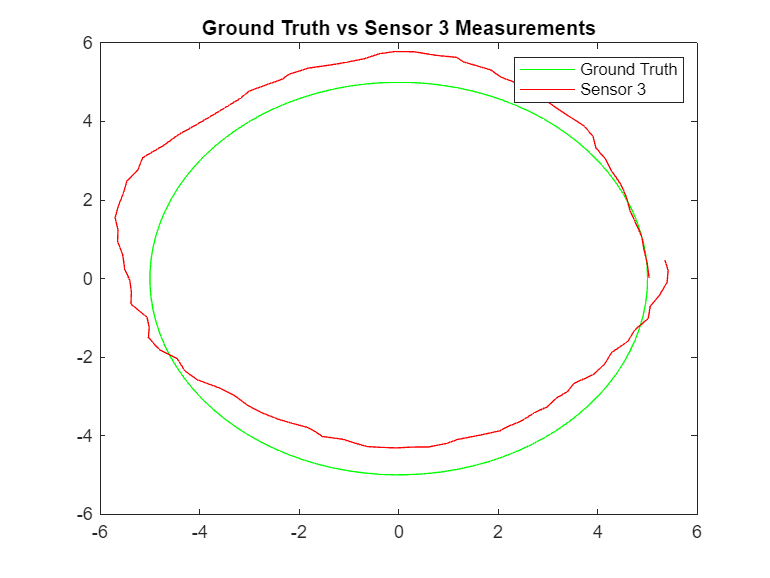

%==================================================
% Load data from data.mat
%==================================================

if ~load_data
    data.circle = circle;
else
    data = load(file_name);
end

% load ground truth
true_x = data.circle.true_x(1:itr);
true_y = data.circle.true_y(1:itr);

% load sensor data
Z = zeros(2,4,itr);

Z(1,1,:) = data.circle.sensor1.x(1:itr);
Z(2,1,:) = data.circle.sensor1.y(1:itr);

Z(1,2,:) = data.circle.sensor2.x(1:itr);
Z(2,2,:) = data.circle.sensor2.y(1:itr);

Z(1,3,:) = data.circle.sensor3.x(1:itr);
Z(2,3,:) = data.circle.sensor3.y(1:itr);

Z(1,4,:) = data.circle.sensor4.x(1:itr);
Z(2,4,:) = data.circle.sensor4.y(1:itr);

Z(1,5,:) = data.circle.sensor5.x(1:itr);
Z(2,5,:) = data.circle.sensor5.y(1:itr);

Z(1,6,:) = data.circle.sensor6.x(1:itr);
Z(2,6,:) = data.circle.sensor6.y(1:itr);

Z(1,7,:) = data.circle.sensor7.x(1:itr);
Z(2,7,:) = data.circle.sensor7.y(1:itr);

Z(1,8,:) = data.circle.sensor8.x(1:itr);
Z(2,8,:) = data.circle.sensor8.y(1:itr);

Z(1,9,:) = data.circle.sensor9.x(1:itr);
Z(2,9,:) = data.circle.sensor9.y(1:itr);

Z(1,10,:) = data.circle.sensor10.x(1:itr);
Z(2,10,:) = data.circle.sensor10.y(1:itr);

Z(1,11,:) = data.circle.sensor11.x(1:itr);
Z(2,11,:) = data.circle.sensor11.y(1:itr);

Z(1,12,:) = data.circle.sensor12.x(1:itr);
Z(2,12,:) = data.circle.sensor12.y(1:itr);

% hold on;
figure;
plot(data.circle.true_x,data.circle.true_y,'g',"DisplayName","Ground Truth");
hold on;
plot(data.circle.sensor3.x,data.circle.sensor3.y,'r',"DisplayName","Sensor 3");
title("Ground Truth vs Sensor 3 Measurements");
legend(["Ground Truth","Sensor 3"]);

## Initialization

% Prediction Step
x_1 = f*init_x;
p_1 = f*init_p*f' + q;

% Network connection
% J = [ 1 2 4; 2 3 1; 3 4 2; 4 1 3];
J = [12 1 2;
     1 2 3;
     2 3 4;
     3 4 5;
     4 5 6;
     5 6 7;
     6 7 8;
     7 8 9;
     8 9 10;
     9 10 11;
     10 11 12;
     11 12 1];

% Storage initialization
X_Est = NaN(6,N,itr); % TODO: Create a variable to store the estimate from the best sensor
P_Est = NaN(6,6,N,itr);

X_Pred = NaN(6,N,itr+1);
P_Pred = NaN(6,6,N,itr+1);

M_I = NaN(6,6,N,itr);
Final_Est = NaN(2,itr,length(EPS));

con_diff = NaN(2,N,itr);

for c = 1:N
    X_Pred(:,c,1) = x_1;
    P_Pred(:,:,c,1) = p_1;
end

MSE = NaN(1,length(EPS));

## Algorithm

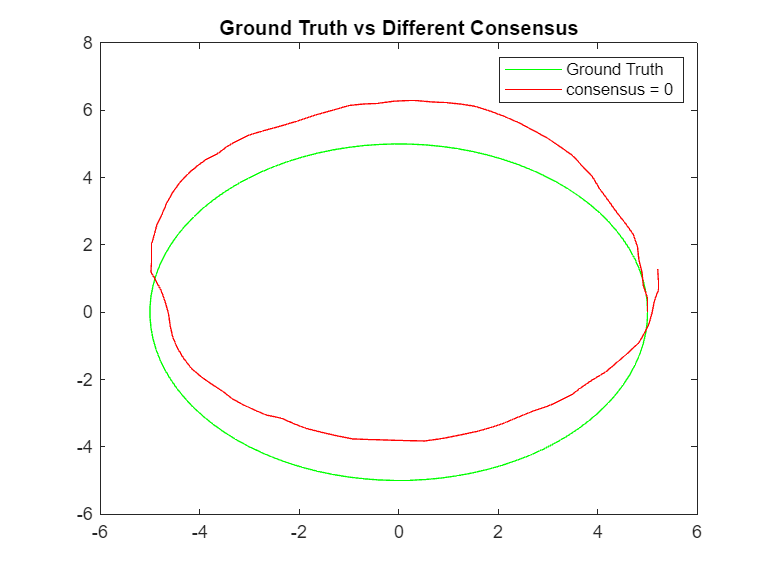

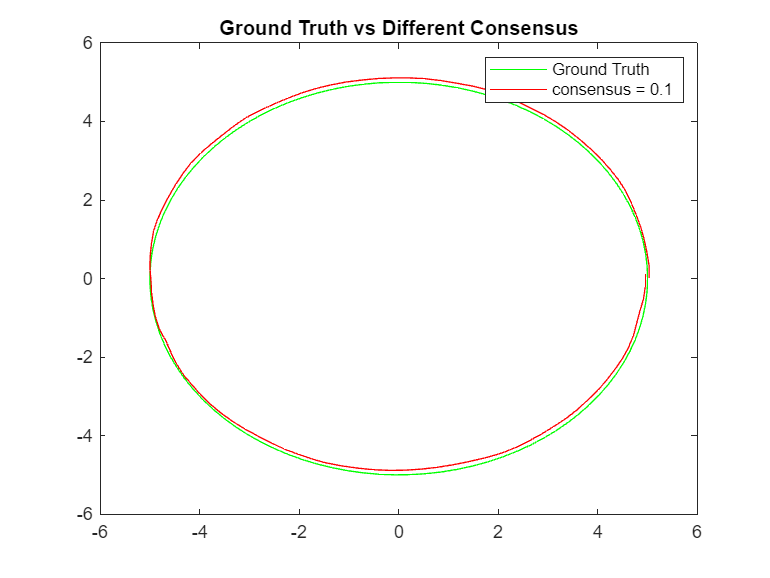

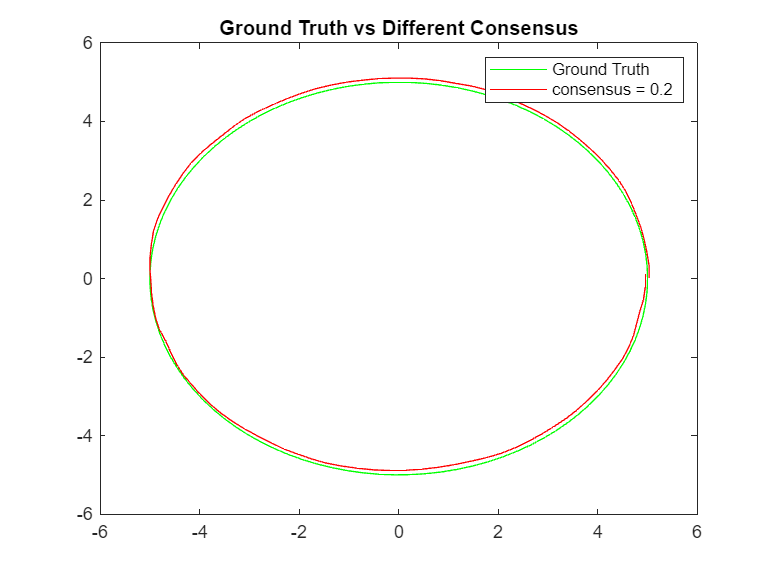

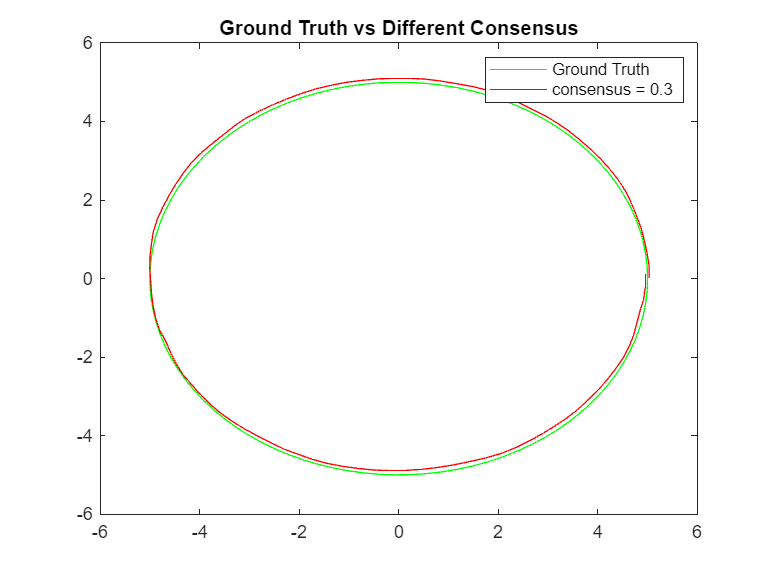

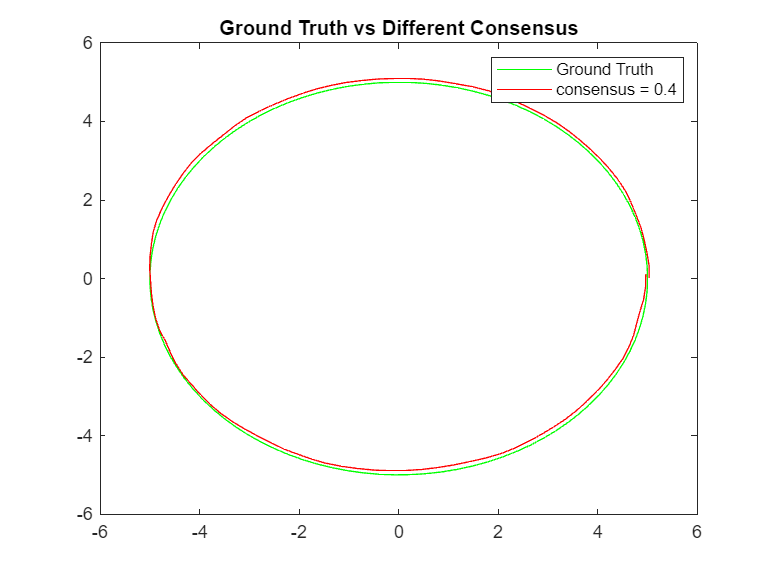

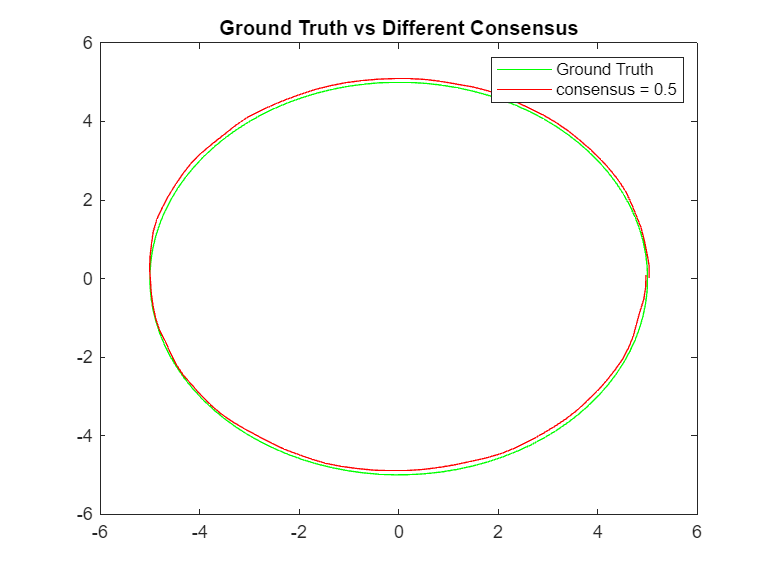

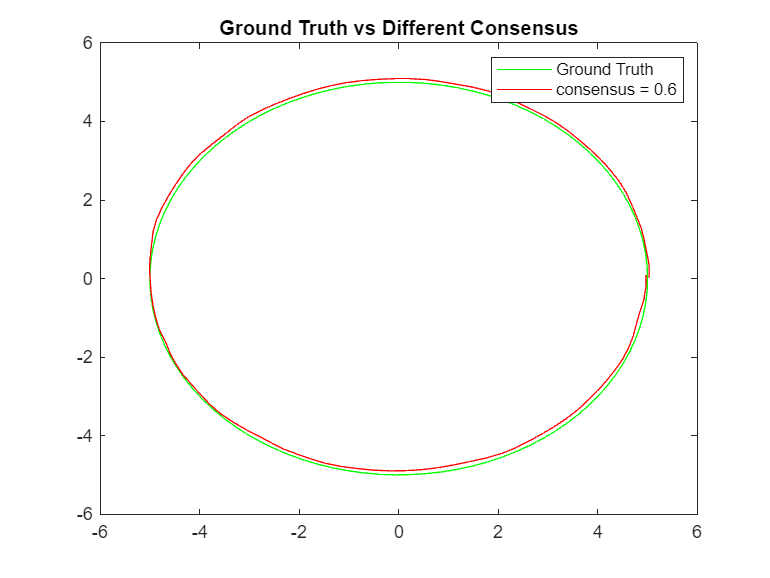

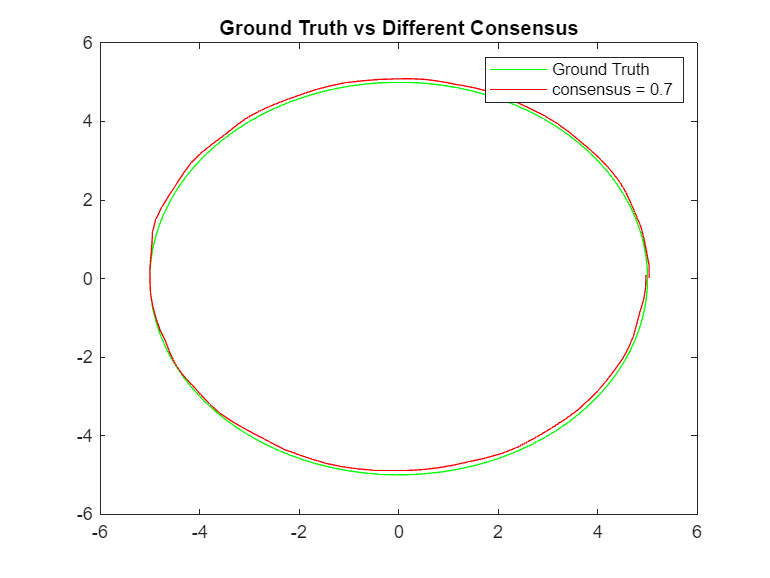

for e = 1:11  % length(eps)
    for i = 1:itr
        % At each iterations
        for n = 1:N
            % for every sensor
            msg.y_n = zeros(6,3); % measurement % N-1 because each sensor can have two neighboring sensor + itself
            msg.s_n = zeros(6,6,3); % covariance
            msg.x_n = zeros(2,3); % state estimate
            for nei = 1:3
                % for every neighbour
                j = J(n,nei);
                h_nei = H(:,:,j);
                r_nei = R(:,:,j);
                z_nei = Z(:,j,i);
                msg.y_n(:,nei) = h_nei' * inv(r_nei) * z_nei;
                msg.s_n(:,:,nei) = h_nei' * inv(r_nei) * h_nei;
                msg.x_n(:,nei) = [X_Pred(1,j,i);X_Pred(4,j,i)];
            end
    
            % current state estimate
            Y_n = zeros(6,1);
            S_n = zeros(6,6);
            x_diff_sum = 0;
            for m = 1:3
                Y_n = Y_n + msg.y_n(:,m);
                S_n = S_n + msg.s_n(:,:,m);
                if m ~= 1
                    x_diff_sum = x_diff_sum + (msg.x_n(:,m) - msg.x_n(:,1));
                end
            end
            con_diff(1,n,i) = x_diff_sum(1,1);
            con_diff(2,n,i) = x_diff_sum(2,1);
            x_diff_sum = [x_diff_sum(1,1) 0 0 x_diff_sum(2,1) 0 0]';
    
            M_i = inv(inv(P_Pred(:,:,n,i)) + S_n);
            M_I(:,:,n,i) = M_i;
            x_p = X_Pred(:,n,i);
            innov = Y_n - (S_n*x_p);
            x_est = x_p + (M_i*innov) + (EPS(e)*M_i*x_diff_sum);
    
            % Update state
            p_next = f*M_i*f' + q;
            x_next = f*x_est;
    
            % Store values
            X_Est(:,n,i) = x_est;
            X_Pred(:,n,i+1) = x_next;
            P_Pred(:,:,n,i+1) = p_next;
        end
        smallest_i = 0;
        smallest_val = inf;
        % select the best estimate from each sensor
        for l = 1:N
            if M_I(1,1,l,i) < smallest_val
                smallest_val = M_I(1,1,l,i);
                smallest_i = l;
            end
        end
        best_x_i = X_Est(1,smallest_i,i);
        best_y_i = X_Est(4,smallest_i,i);
        Final_Est(:,i,e) = [best_x_i;best_y_i];
    end
    figure;
    plot(data.circle.true_x,data.circle.true_y,'g',"DisplayName","Ground Truth");
    px = Final_Est(1,:,e);
    py = Final_Est(2,:,e);
    hold on;
    str = "consensus = " + EPS(e);
    plot(px,py,'r',"DisplayName",str);
    title("Ground Truth vs Different Consensus");
    legend(["Ground Truth",str])
    % Individual points error
    summ = 0;
    for c = 1:itr
        sqr_error = (Final_Est(1,c,e) - true_x(1,c))^2 + (Final_Est(2,c,e) - true_y(1,c))^2;
        summ = summ + sqr_error;
    end
    MSE(:,e) = summ / itr;
end

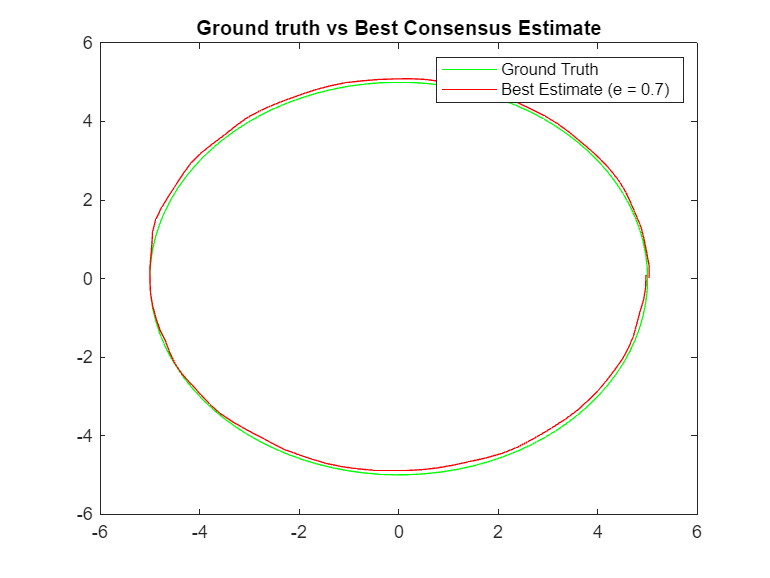

opt_est = NaN(2,itr);
[t,optimal_e] = min(MSE);
opt_est(:,:) = Final_Est(:,:,optimal_e);

% Ground Truth vs Estimate
figure;
plot(true_x,true_y,'g',"DisplayName","Ground Truth");
hold on;
str = "Best Estimate (e = " + EPS(optimal_e) + ")";
plot(opt_est(1,:),opt_est(2,:),'r',"DisplayName",str);
title("Ground truth vs Best Consensus Estimate");
legend(["Ground Truth",str]);

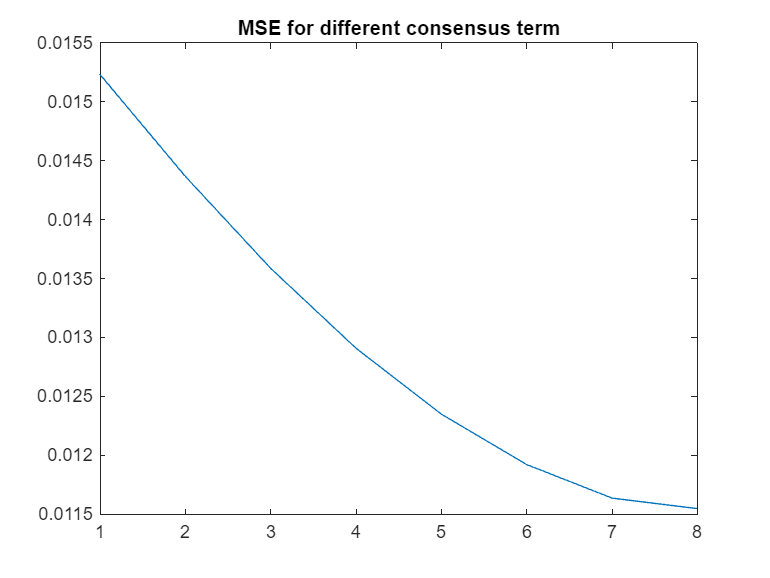

% MSE Plot
figure;
plot(MSE(1:optimal_e));
title("MSE for different consensus term");